## 0. channel object 생성 및 데이터 처리: reading_method_guide.mlx 참고

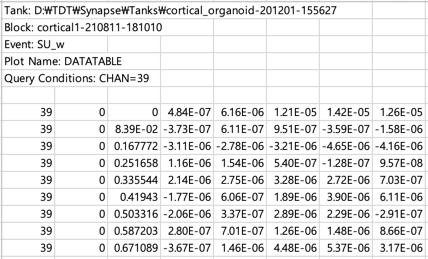

reader = channelReader();
tic
                                    % filename,                        timeColumnIdx  startRowIdx   startColIdx   sampleRate   organoidNum        channelNum     month
o1_ch39_m4 = reader.readSingleChannel("/Users/mac/Documents/GitHub/14w_ch39_su.xlsx", 3,      7,             4,            nan,           1,              39,            4);

toc

경과 시간은 88.343526초입니다.


**0.3.1 (method) **`bandPass`

**bandpass filter 적용**

**파라미터 1개 **

- `passBand` : [숫자, 숫자] 포맷으로, hz 단위로 입력

 bandpass filter 실제로 적용하여 channel object 내에 저장

o1_ch39_m4.bandPass([300,3000]); %apply bandpass filter 300-3000hz

**0.4. (method) **`detectSpikes`

**spike detection 수행**

**paramter 3개**

- `thres`: spike 분류 기준. 5를 입력하면 평균+5표준편차 밖의 값을 spike로 분류 ((reference code에서는 5)

- `preTime`: spike waveform의 spike 앞쪽 너비. milisecond 단위 (reference code에서는 2)

- `postTime`: spike waveform의 spike 뒷쪽 너비. milisecond 단위 (reference code에서는 2)

주의: 코드 내 threshold에 minus가 붙어 있음, 즉 이 알고리즘은 local minimum을 찾는 알고리즘. 레퍼런스 코드에서 이렇게 구현되어 있었음.

                        %thres, preTime, postTime
o1_ch39_m4.detectSpikes(5,2,2);

number of spikes found : 1696


**0.4.1. (method) **`getISIvaluesBeforePCA`

PCA 및 k-means를 통해 spike들을 cluster별로 나누기 전에, 발견한 모든 spikes를 대상으로 ISI 계산**(milisecond 단위)**하고 data 가져오는 method:

- `channelobject.getISIvaluesBeforePCA()`

**paramter 없음**

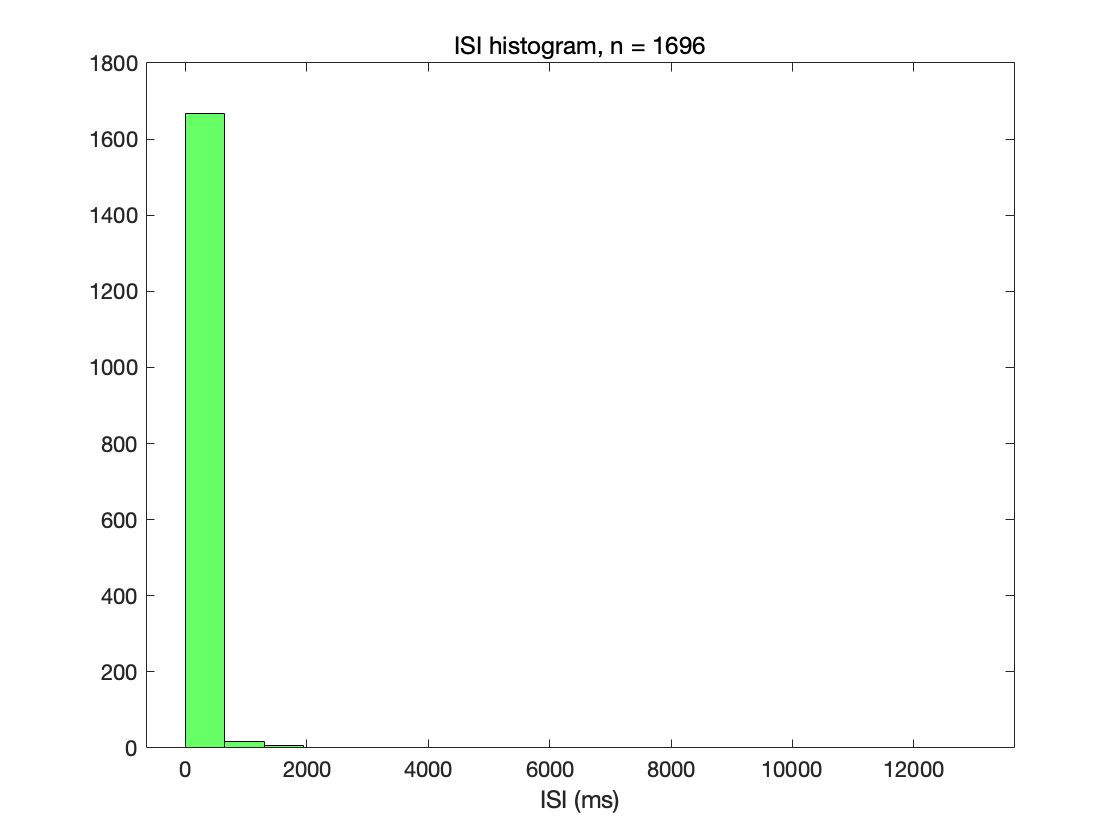

ISIvaluesBeforePCA = o1_ch39_m4.getISIvaluesBeforePCA(); %PCA, kmeans 전에 전체 spike 대상 ISI 계산값 가져오기
nSpikes = o1_ch39_m4.nSpikes;

figure
h1 = histogram(ISIvaluesBeforePCA, 20); % bin 개수 20개로 설정. 변경 가능
title('ISI histogram, n = ' + string(nSpikes) ); %plot 제목 
xlabel('ISI (ms)'); % plot x축 변수 이름
h1.FaceColor = "green"; %색상 지정

#### **0.4.2. (method) detectBurstsMI**

**MaxInterval method를 이용한 non-network burst detection**

% begISI, endISI , minSpikes, minDurn, minIBI, (in milisecond)
% the order of the parameters is the same as the reference [1]
burstDetectionResult = o1_ch39_m4.detectBurstsMI(300, 301, 10, 50, 200) %[1]과 똑같은 parameter 값을 사용

phase 1 result: found 55 bursts, using parameters begISI and endISI

phase 2 result: after merging by minIBI, 55 bursts left

phase 3 result: 39 bursts were removed whose duration is less than 50 milisecond or have spikes less than 10 

burstDetectionResult = 16×6 table
    beg     end      IBI      nSpikes     durn     meanISI
    ____    ____    ______    _______    ______    _______

      38     395       NaN      358       12857    36.013 
     396     597    310.19      202      8111.4    40.355 
     598     761    302.94      164      7659.7    46.992 
     762     787    366.18       26       997.7    39.908 
     788    1263    337.06      476       18086    38.075 
    1267    1360    873.39       94      5791.9    62.279 
    1361    1381    360.78       21      1706.4    85.322 
    1382    1403    511.02       22        1328    63.236 
    1424    1434    4037.7       11      888.91    88.891 
    1456    1481    6226.4       26      1640.9    65.634 
    1482    1506    720.65       25      224.79    9.3662 
    1516    1531      5801       16      651.92    43.461 
    1541    1559    9083.1       19      1052.9    58.495 
    1561    1575    1198.4       15      744.16    53.154 
    1578    1630    1

**0.5. (method) **`getPCScores`

**PCA 수행**

주의

- PCA는 각 축의 분산을 최대한 보존하는 principal component를 찾는 알고리즘이므로, 특정 waveform의 scale이 지나치게 크다면 분산에 많이 기여하게 되어 그 waveform을 principal component로 잘못 인식할 수 있음. 일반적으로 PCA를 비롯한 차원축소 알고리즘들이 비슷한 문제를 가지고 있기 때문에, 알고리즘 수행 전에 각 데이터포인트의 scale을 통일하는 scaling을 필수적으로 수행함

- Scaling 방법은평균을 빼고 표준편차로 나누는 standard scaling, min을 빼고 (max-min)으로 나누는 0-1 scaling 등이 있음

- 물론 데이터가 scale이 원래 일정하다면 굳이 standardization을 수행할 필요가 없음. Reference code에서는 standard scaling 코드를 써 놓고 주석 처리해 놓았음. 이 코드에서는 주석 처리를 해제하고 standard scaling을 수행하도록 하였음

- PCA 수행 후 explained variance plot을 꼭 확인해야 함. 첫 두 PC가 설명하는 분산의 양이 충분히 커야(보통 70% 이상) 2차원만 남기고 나머지 차원을 버리는 것이 정당화됨

- **경고 메시지 "X의 열은 기계 정밀도 내에서 1차 종속입니다"는 spike waveform의 시작과 끝 부분이 평탄해서 비슷한 값을 가지기 때문에 발생. 어차피 PCA를 통해서 차원축소를 할 것이기 때문에 문제되지 않음**

o1_ch39_m4.getPCScores();

**0.6. (method) **`getKmeansClusters`

**K-means clustering 수행**

**parameter 2개**

- `clusternum`: cluster 개수(reference code에선 3)

- `seednum`: 알고리즘의 초기값에 영향을 미치는 random number seed(reference code에 없음)

주의

- k-means clustering은 해를 해석적으로 구하지 못하고 EM algorithm이라는 iterative algorithm을 사용하는데, 초기값에 큰 영향을 받음. 초기값이란 각 점의 맨 처음 cluster 배정을 의미하며, 랜덤으로 할당함. 일반적으로 이러한 EM algorithm 기반 clustering을 수행할 때는 여러 seed number를 사용하여 알고리즘을 여러 번 돌려봄.

- k-means clustering에서 cluster 개수(clusternum)는 자동으로 최적값이 정해지지 않으며, 정답이 없는 비지도학습이기에 최적값을 알 수도 없음. 일반적으로 사용자가 여러 clusternum을 시도해 보며 적절한 값을 찾아야 함.

- 결론적으로, 여러 clusternum과 seednum의 조합을 시도하면서 plot을 보고 사용자 눈에 적절한 결과가 나올때까지 진행해야 함.

                           %clusternum, seednum
o1_ch39_m4.getKmeansClusters(25,1);

number of spikes per cluster:
cluaster 1: 600 
cluaster 2: 1 
cluaster 3: 62 
cluaster 4: 1 
cluaster 5: 1 
cluaster 6: 1 
cluaster 7: 2 
cluaster 8: 1 
cluaster 9: 1 
cluaster 10: 1 
cluaster 11: 100 
cluaster 12: 1 
cluaster 13: 1 
cluaster 14: 1 
cluaster 15: 273 
cluaster 16: 2 
cluaster 17: 7 
cluaster 18: 148 
cluaster 19: 138 
cluaster 20: 343 
cluaster 21: 1 
cluaster 22: 1 
cluaster 23: 4 
cluaster 24: 4 
cluaster 25: 1 
spike가 한 개 이하인 클러스터가 존재하므로 클러스터별 ISI를 계산할 수 없습니다. seed number를 다르게 하거나, 클러스터 개수를 줄여야 합니다.
